1. Sampling a cosine signal

Generate a cosine signal and plot its spectrum with sampling interval Ts = 1/100. Find the spectrum of the cosine signal cos(2 pi f t) when f=30, 40, 49, 50, 51, 60 Hz. Which of these show aliasing?

Ts = 1/100

Ts = 0.0100

fs = 1/Ts

fs = 100

t = Ts:Ts:(2*pi)

t =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


fx = [30, 40, 49, 50, 51, 60] 

fx =     30    40    49    50    51    60


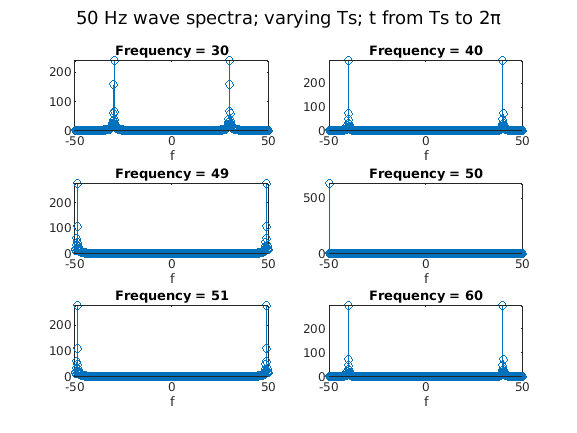

for i=1:1:6
   x = cos(2 * pi * fx(i) .* t);
   subplot(3, 2, i);
   stem(t, abs(fftshift(fft(x))));
   freqTitle = "Frequency = " + fx(i);
   title(freqTitle);
    xticks(Ts:(pi-Ts):(2*pi)-Ts)
    xticklabels([-50 0 50])
    xlabel("f")
end
sgtitle("50 Hz wave spectra; varying Ts; t from Ts to 2π")

2. Experimenting different sampling invervals 

Generate a cosine signal with frequency 50 Hz. Plot the spectrum when this signal is sampled at Ts = 1/50, 1/90, 1/100, 1/110, and 1/200. Which of these show aliasing?

% code 
T_samp = [1/50, 1/90, 1/100, 1/110, 1/200]

T_samp =     0.0200    0.0111    0.0100    0.0091    0.0050


F_samp = [ 50,   90,   100,   110,   200 ]

F_samp =     50    90   100   110   200


for i=1:1:5
    subplot(3, 2, i);
    Ts = T_samp(i);
    t = 0:Ts:(2*pi)+Ts;
    x = cos(2 * pi * 50 .* t)
    x_fft = abs(fftshift(fft(x)));
    stem(t, x_fft);
    title("Ts = 1/" + F_samp(i));
    xticks(Ts:(pi-Ts):(2*pi)-Ts)
    min = -F_samp(i) / 2;
    max = (F_samp(i)/2)
    xticklabels([min 0 max])
    xlabel("f")
end

x =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


max = 25

x =     1.0000   -0.9397    0.7660   -0.5000    0.1736    0.1736   -0.5000    0.7660   -0.9397    1.0000   -0.9397    0.7660   -0.5000    0.1736    0.1736   -0.5000    0.7660   -0.9397    1.0000   -0.9397    0.7660   -0.5000    0.1736    0.1736   -0.5000    0.7660   -0.9397    1.0000   -0.9397    0.7660   -0.5000    0.1736    0.1736   -0.5000    0.7660   -0.9397    1.0000   -0.9397    0.7660   -0.5000    0.1736    0.1736   -0.5000    0.7660   -0.9397    1.0000   -0.9397    0.7660   -0.5000    0.1736


max = 45

x =      1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1


max = 50

x =     1.0000   -0.9595    0.8413   -0.6549    0.4154   -0.1423   -0.1423    0.4154   -0.6549    0.8413   -0.9595    1.0000   -0.9595    0.8413   -0.6549    0.4154   -0.1423   -0.1423    0.4154   -0.6549    0.8413   -0.9595    1.0000   -0.9595    0.8413   -0.6549    0.4154   -0.1423   -0.1423    0.4154   -0.6549    0.8413   -0.9595    1.0000   -0.9595    0.8413   -0.6549    0.4154   -0.1423   -0.1423    0.4154   -0.6549    0.8413   -0.9595    1.0000   -0.9595    0.8413   -0.6549    0.4154   -0.1423


max = 55

x =     1.0000    0.0000   -1.0000   -0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000   -0.0000


max = 100

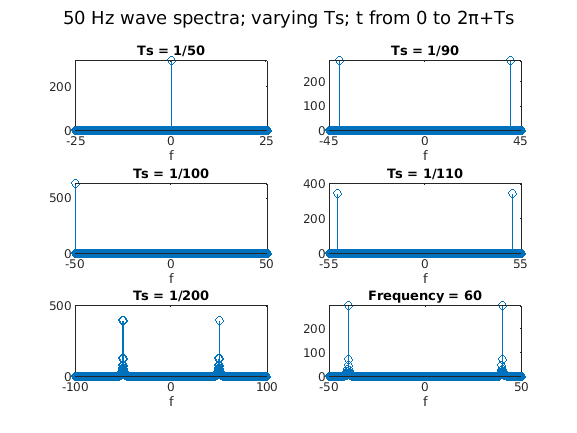

sgtitle("50 Hz wave spectra; varying Ts; t from 0 to 2π+Ts")

3. Generate a cosine signal similar to Exercise 1. Create a square signal with fundamental f = 10, 20, 30, 33, 43, and sample it with Ts = 1/100 to find the spectrum.

Can you predict where the spikes will occur in each case? Which of the square signals show aliasing?

max = 49.9900

max = 49.9900

max = 49.9900

max = 49.9900

max = 49.9900

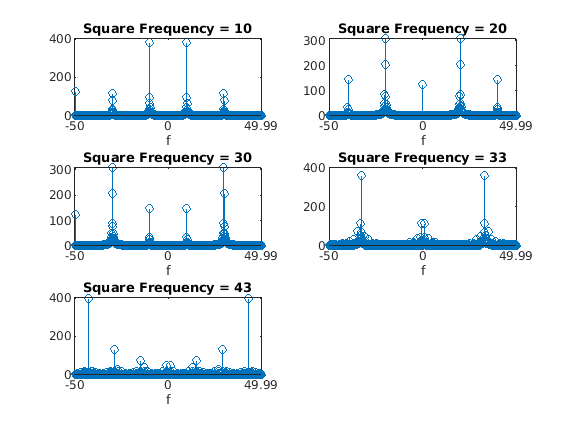

fs = 100;
Ts = 1/fs;
t = Ts:Ts:2*pi;
F0 = [10 20 30 33 43];
figure(3)
for i = 1:1:5
    square_wv = sign(cos(2 * pi * F0(i) .* t));
    subplot(3, 2, i);
    stem(t, abs(fftshift(fft(square_wv))));
    title("Square Frequency = " + F0(i))
    
    xticks(Ts:(pi-Ts):(2*pi)-Ts)
    min = -fs / 2;
    max = fs/2 - Ts
    xticklabels([min 0 max])
    xlabel("f")
end

Sample square wave completely contained in dft:

fs = 100;
Ts = 1/fs;
t = Ts:Ts:2*pi;
F0 = 2;
Fsum = zeros(length(t))';
for i = 1:2:5
    Fsum = Fsum + 1/i * (cos(pi/2 + 2 * pi * F0 * i .* t))';
end
Fsum = Fsum(:, [1])

Fsum =    -0.3656
   -0.6671
   -0.8599
   -0.9320
   -0.9048
   -0.8238
   -0.7409
   -0.6959
   -0.7044
   -0.7551


figure(4);
subplot(2, 1, 1);
plot(t, Fsum);
xlabel("Time");
ylabel("Square Wave Amplitude");
xlim([0 2*pi])
xticks([2*pi])
xticklabels("2π")

subplot(2,1,2);
square_spectra = abs(fftshift(fft(Fsum)));
stem(t, square_spectra);
xlabel("f");
ylabel("Square Wave Spectra");

xticks(Ts:(pi-Ts):(2*pi)-Ts)
min = -fs / 2;
max = fs/2 - Ts

max = 49.9900

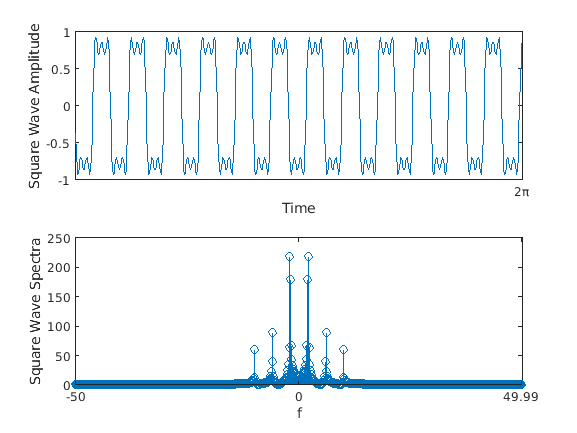

xticklabels([min 0 max])
xlim([0 2*pi])